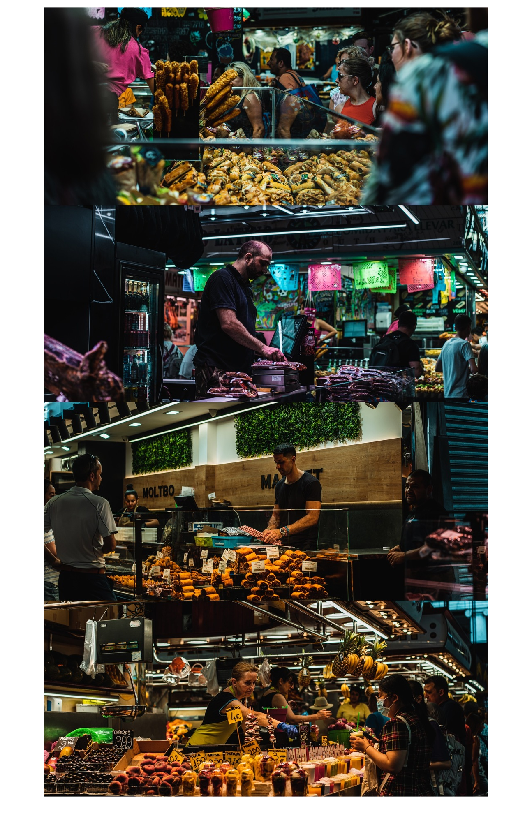

% read the small images
smallImgAmt = 400;
smallBlocks = cell(smallImgAmt, 1);
smallBlockCIELAB = zeros(smallImgAmt, 3);

blockSize = 20;

factor = blockSize / 100;

% CREATE LOOK-UP TABLE
for i = 1:smallImgAmt
    folder = 'Dataset1';
    filename = strcat('image', num2str(i), '.jpg');
    filepath = fullfile(folder, filename);
    img = imread(filepath);

    filename = strcat( 'image', num2str(i), '.jpg');
    smallImg = im2double(imresize(img,factor));
    smallBlocks{i} = smallImg;
    smallBlockCIELAB(i,:) = mean(mean(squeeze(applycform(smallImg, makecform('srgb2lab')))));
end

%%

% read the large image
largeImage = im2double(imread('test.jpg'));
largeImage_original = im2double(imread('test.jpg'));
imshow(largeImage_original);

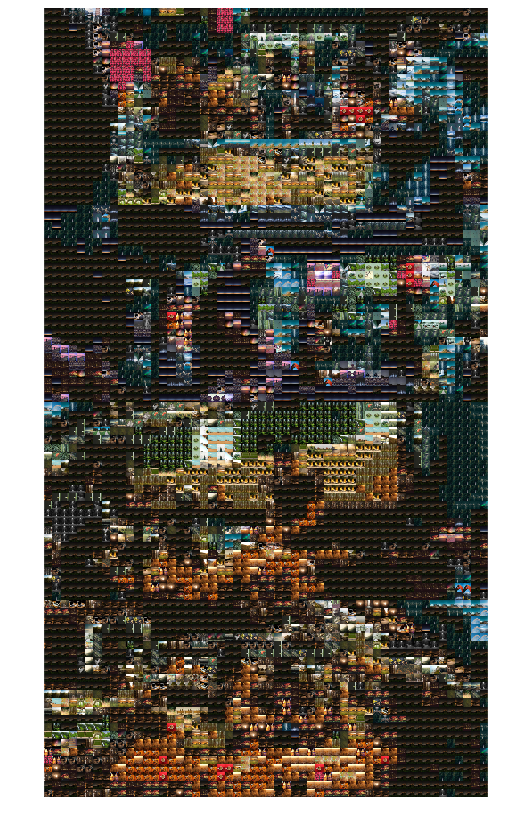


% divide the large image into non-overlapping 10x10 pixel blocks

numBlocksRow = size(largeImage, 1) / blockSize;
numBlocksCol = size(largeImage, 2) / blockSize;
largeBlocks = cell(floor(numBlocksRow), floor(numBlocksCol));


for i = 1:numBlocksRow
    for j = 1:numBlocksCol
        rowStart = (i-1)*blockSize + 1;
        rowEnd = i*blockSize;
        colStart = (j-1)*blockSize + 1;
        colEnd = j*blockSize;
        largeBlocks{i, j} = largeImage(rowStart:rowEnd, colStart:colEnd, :);
    end
end

tic;
% compute the average CIELAB value for each large block
for i = 1:numBlocksRow
    for j = 1:numBlocksCol
        largeBlocks{i, j} = mean(mean(squeeze(applycform(largeBlocks{i, j}, makecform('srgb2lab')))));
    end
end

% reconstruct the large image using the small images
for i = 1:numBlocksRow
    for j = 1:numBlocksCol
        % find the small image with the closest CIELAB value to the current large block
        minDistance = Inf;
        for k = 1:smallImgAmt
            largeBlockVec = reshape(largeBlocks{i, j}, 1, []);
            smallBlockVec = reshape(smallBlockCIELAB(k,:), 1, []);
            %smallBlockVec = reshape(mean(mean(squeeze(applycform(smallImages{k}, makecform('srgb2lab'))))), 1, []);
            
            % compute the Euclidean distance between the 1D vectors using norm
            distance = norm(largeBlockVec - smallBlockVec);

            if distance < minDistance
                minDistance = distance;
                bestImage = smallBlocks{k};
            end
        end
        
        % replace the current large block with the best matching small image
        rowStart = (i-1)*blockSize + 1;
        rowEnd = i*blockSize;
        colStart = (j-1)*blockSize + 1;
        colEnd = j*blockSize;
        largeImage(rowStart:rowEnd, colStart:colEnd, :) = bestImage;
    end
end
timesz = toc;
% display the reconstructed image
imshow(largeImage);


filename2 = strcat('Cu_', num2str(smallImgAmt), '_time-', num2str(timesz), '_',num2str(blockSize),'x',num2str(blockSize),'.png');

imwrite(largeImage,filename2)
